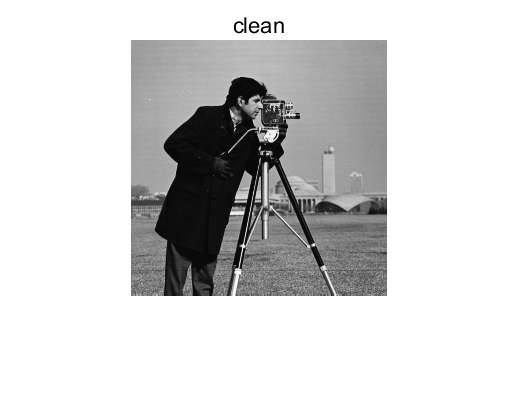

clc; clear all;
img_clean = imread('cameraman.tif');
imshow(img_clean)
title("clean");

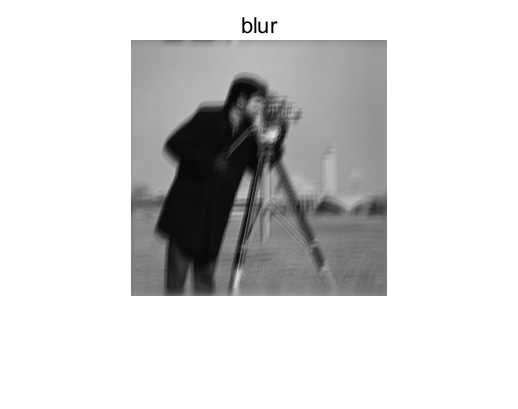

%TV NonblindDeblur
load('blur_cameraman.mat')
img_blur = blur * 255;
img_deblur = TV_NonblindDeblur(img_blur, kernel, 0.26, 0.05);

imshow(uint8(img_blur))
title('blur')

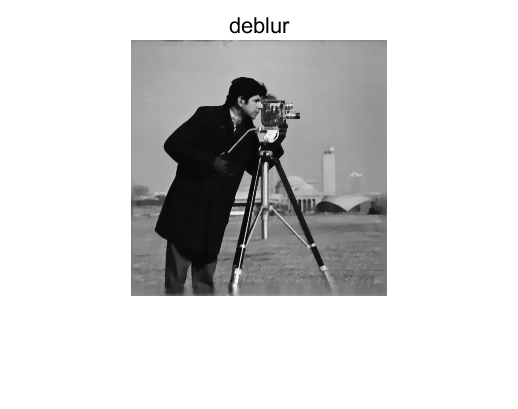


imshow(uint8(img_deblur))
title('deblur')


psnr(uint8(img_deblur), img_clean)

ans = 28.9277

ssim(uint8(img_deblur), img_clean)

ans = 0.8579